f=@(x) exp(x)

f = function_handle with value:
    @(x)exp(x)


x = linspace(-1,1)

x =    -1.0000   -0.9798   -0.9596   -0.9394   -0.9192   -0.8990   -0.8788   -0.8586   -0.8384   -0.8182   -0.7980   -0.7778   -0.7576   -0.7374   -0.7172   -0.6970   -0.6768   -0.6566   -0.6364   -0.6162   -0.5960   -0.5758   -0.5556   -0.5354   -0.5152   -0.4949   -0.4747   -0.4545   -0.4343   -0.4141   -0.3939   -0.3737   -0.3535   -0.3333   -0.3131   -0.2929   -0.2727   -0.2525   -0.2323   -0.2121   -0.1919   -0.1717   -0.1515   -0.1313   -0.1111   -0.0909   -0.0707   -0.0505   -0.0303   -0.0101


y = f(xx)

y =     0.3679    0.3754    0.3830    0.3909    0.3988    0.4070    0.4153    0.4238    0.4324    0.4412    0.4502    0.4594    0.4688    0.4784    0.4881    0.4981    0.5083    0.5186    0.5292    0.5400    0.5510    0.5623    0.5738    0.5855    0.5974    0.6096    0.6220    0.6347    0.6477    0.6609    0.6744    0.6882    0.7022    0.7165    0.7312    0.7461    0.7613    0.7768    0.7927    0.8089    0.8254    0.8422    0.8594    0.8769    0.8948    0.9131    0.9317    0.9507    0.9702    0.9899


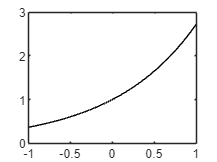

plot(xx,yy,'k-')

a = -1

a = -1

b = 1

b = 1

Itrue = exp(1) - exp(-1)

Itrue = 2.3504

[I_romberg,ea,iter] = romberg(f,a,b,0.5)

I_romberg = 2.3505

ea = 0.0308

iter = 2

a1 = (b+a) / 2

a1 = 0

a2 = (b-a) / 2

a2 = 1


%x = a1+a2*xd
%dx - a2*dxd
%f=@(x) 400.*x.^5 - 900.*x.^4 + 675.*x.^3 - 200.*x.^2 + 25.*x + 0.2;
f2=@(xd) (exp(a1+a2.*xd).*a2)

f2 = function_handle with value:
    @(xd)(exp(a1+a2.*xd).*a2)


I_2points = f2(-1/sqrt(3)) + f2(1/sqrt(3))

I_2points = 2.3427


I_3points = (5/9)*f2(-sqrt(3/5)) + (8/9)*f2(0) + (5/9)*f2(sqrt(3/5))

I_3points = 2.3503

q = quadadapt(f,a,b,0.5)

q = 2.3505

sum = integral(f,a,b)

sum = 2.3504